% ojo, aca interpolas puntos [tiempo, theta]


P=[linspace(0,30,length(theta1ns'))',theta1ns'];
P(2,1)=P(2,1)+3;
P(3:end,1)=P(3:end,1)+P(2,1);
P(end,1)=P(end,1)+3;
Puntos = P(:);

P1=zeros(size(P,1),6);
for i=1:size(P,1)
%     esto eleva el tiempo a la 5 , la 4, ala 3, 2...
% queda una fila por cada punto temporal
% y las 6 derivadas del tiempo en filas
    P1(i,:)=[det(P(i,1)*eye(5)),det(P(i,1)*eye(4)),det(P(i,1)*eye(3)),det(P(i,1)*eye(2)),P(i,1),1];
end
% M: matriz derivada
M=[1,1,1,1,1,1;5,4,3,2,1,0;20,12,6,2,0,0];
% doble matriz derivada
MM=[M;M];

Z=zeros(6,6);

sUP=zeros(6*(size(P,1)-1),6*(size(P,1)-1))

sUP =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

for i=1:(size(P,1)-1)
%     los indices 6*i-5:6*i,6*i-5:6*i
%  son de 1 a 6, luego 7 a 12 y asi
% osea se va llenando la matriz grande, a partir de 
% pequeñas 6x6 en la "diagonal"
    sUP(6*i-5:6*i,6*i-5:6*i)=[M.*[P1(i,:);[P1(i,2:end),0];[P1(i,3:end),0,0]]; M.*[P1(i+1,:);[P1(i+1,2:end),0];[P1(i+1,3:end),0,0]]];
end

% condiciones de posicion
baux=[];
% llena repitiendo 2 veces vector b
for j=1:size(P,1)
   baux= [baux,P(j,2),P(j,2)];
    
end
% quita la repeticion del primero y ultimo
baux = baux(2:end-1);

% llena el vector b con posiciones cada 3
b2=zeros(size(sUP,1),1);
cont=0;
for i=1:3:size(sUP,1)
    cont=cont+1;
 b2(i)=baux(cont);
end

% condiciones de velocidad
velocidad=zeros(1,length(baux))+0;

cont=0;
for i=2:3:(size(P,1)*2-2)*3
    cont=cont+1;
 b2(i)=velocidad(cont);
 
end

% condiciones de velocidad
aceleracion=zeros(1,length(baux));

cont=0;
for i=3:3:(size(P,1)*2-2)*3
    cont=cont+1;
 b2(i)=aceleracion(cont);

end
aff=sUP\b2;

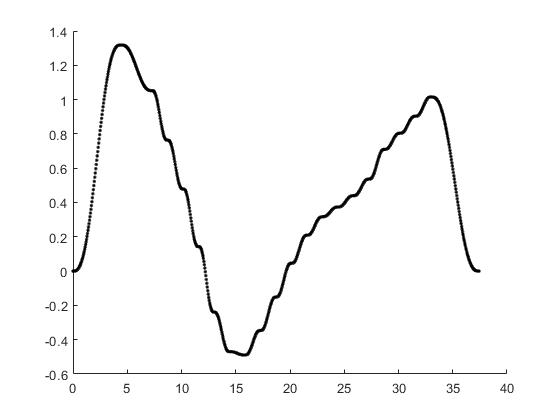


% separacion=0.01;

hold on
thetan=[];
tn=[];

% for
i=1;
% x=P(i,1):separacion:(P(i+1,1));
x=linspace(P(i,1),P(i+1,1),100);
y=aff(6*i-5)*x.^5+aff(6*i-4)*x.^4+aff(6*i-3)*x.^3+aff(6*i-2)*x.^2+aff(6*i-1)*x+aff(6*i);
plot(x,y,'.k')
tn=[tn,x(1:end-1)];
thetan=[thetan,y(1:end-1)];
separacion=x(2)-x(1);

% end
for i=2:size(P,1)-1-1
x=P(i,1):separacion:(P(i+1,1));
% x=linspace(P(i,1),P(i+1,1),3);
y=aff(6*i-5)*x.^5+aff(6*i-4)*x.^4+aff(6*i-3)*x.^3+aff(6*i-2)*x.^2+aff(6*i-1)*x+aff(6*i);
plot(x,y,'.k')
tn=[tn,x(1:end-1)];
thetan=[thetan,y(1:end-1)];
end

i=size(P,1)-1;
% for i=2:size(P,1)-1-1
% x=P(i,1):separacion:(P(i+1,1));
x=linspace(P(i,1),P(i+1,1),100);
y=aff(6*i-5)*x.^5+aff(6*i-4)*x.^4+aff(6*i-3)*x.^3+aff(6*i-2)*x.^2+aff(6*i-1)*x+aff(6*i);
plot(x,y,'.k')

tn=[tn,x];
thetan=[thetan,y];
% end


% csvwrite('stheta1.csv',thetan1)


ttheta1=timeseries(thetan,tn)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [820x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x820 double]
        DataInfo: 

% ttheta2=timeseries(thetan,tn)